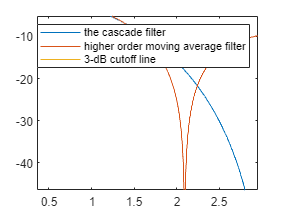

clear;
w = linspace(0,pi,5000);
M = 3;
H_cascade = exp(-j*3*w/2).*(cos(w/2)).^3;
H_moving_average = (1/M)*sin(M.*w/2)./sin(w/2).*exp(-1j*(M-1).*w./2);
plot(w,20*log10(abs(H_cascade)));
hold on;
plot(w,20*log10(abs(H_moving_average)));
plot(w,-3*ones(1,5000));
ylim([-50,0]);
legend('the cascade filter','higher order moving average filter','3-dB cutoff line');